# Modeling and Optimizing a Battery Charging Profile

In this project, you will use MATLAB to model a battery charging profile. You will fit real lithium‑ion battery data in MATLAB, compute energy transfer through numerical integration, and analyze key performance characteristics such as charge‑rate behavior and efficiency losses.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Given data for a lithium-ion battery charging profile, use MATLAB to fit the equation for voltage provided in the Project Description.

- Plot the following curves: voltage vs. time, current vs. time, and power vs. time.

- Use integration to compute the total energy delivered to the battery (area under power-time curve).

- Analyze the rate of voltage change at different intervals (calculate derivatives), compute the time to reach 80% and 100% charge, and compute the energy lost due to resistance.

## Break Down the Problem

**In the space below, define the problem statement:**

Develop a MATLAB program that models and analyzes a lithium battery charging profile using the voltage, power and current vs time data provided to us. This project aims to model a battery charging as a simple first-order RC system, then asks us to estimate a tau value (R*C) by generating a fitted charging-curve model, create three subplots with their respective y-axis values, and perform graphical analysis to meet the designated guidelines.

**List the requirements, constraints, and success criteria for the project:**

A parameter that constrains our project model is the energy that is lost to heat in the battery (due to resistance). Looking at this question another way, an implied constraint/requirement to our project is that we only need to consider the charging portion of the battery charging data cycles, not the discharging portion. The size of the data table provided is also a constraint in a sense because there is a substantial amount of data, whereas for some task steps we only need to consider one data cycle.

**What is your proposed solution?**

Create a MATLAB live script that imports and analyzes the given battery charging data, generates the appropriate graphs for visualization and performs numerical analysis using integration and differentiation to answer all inquiries needed to fulfill the project's criteria. Additionally, we plan to incorporate beneficial features to improve our submission, including but not limited to: adding the option to choose which cycle is to be analyzed, splitting the data into two regions (CC and CV phases), and using Simscape Battery to model/compare various charging profiles.

**List the steps you will need to take to achieve your proposed solution:**

- Import and organize the lithium-ion battery dataset.

- Utilize MATLAB's curve fitting toolbox to compare different charging cycles at various times using multiple models.

- Plot the battery's voltage data alongside with any additional data such as indexes, capacities or residuals.

- Generate voltage, current and power vs time subplots with appropriate axes, titles and legends.

- Compute the derivative of the voltage data using the gradient function.

- Calculate the time required for the battery to reach 80% and 100% charge.

- Compute the total energy delivered to the battery using integration to calculate the area under the power vs time curve.

- Estimate the energy loss through the battery's internal resistance that's converted to heat.

- Summarize findings and analytical results into a MATLAB table.

**What challenges do you face in the process of achieving the solution?**

Some challenges that will be faced include researching the properties and behavior of lithium-ion batteries over time, processing a large dataset and finding a way to only extract one desired cycle from it, and understanding the equations and properties of an RC circuit used to model the battery charging profile.

**See File Here: **[https://docs.google.com/document/d/13nM_2UrytXOp5KPKIsGGzpxkrW3S420AQZLhab-gH38/edit?usp=drive_link](https://docs.google.com/document/d/13nM_2UrytXOp5KPKIsGGzpxkrW3S420AQZLhab-gH38/edit?usp=drive_link) 

## Task 1: Fit the voltage equation to a lithium-ion battery profile

Given real time-series voltage data for a lithium-ion battery, use MATLAB Curve Fitting Toolbox to fit the equation $V\left(t\right)=V_{\max } \left(1-e^{-\frac{t}{\mathrm{RC}}} \right)$ and model the battery charging profile as a simple RC-circuit analog.

Load MathWorks example lithium-ion batteries data by following the steps [here](https://www.mathworks.com/help/predmaint/ug/data-analysis-and-feature-extraction-for-battery-raw-cycling-data.html). The page also includes information about the dataset, how the data was recorded, and the battery's maximum voltage.

**Note**: The battery from this example dataset has been cycled to failure (charged and discharged repeatedly). For this project, you may choose to use data from a single cycle and focus only on the period of time within a cycle that the battery is being charged. The battery is fully charged at 3.6V. This example battery uses a dynamic fast charging profile, but for this project, you will attempt to model the charging profile using a simple exponential capacitor charging equation.

Then, follow the workflow outlined in the [documentation](https://www.mathworks.com/help/curvefit/fit.html) to fit the voltage equation to your selected data. Plot the data and fitted curve in the same figure and, finally, print the goodness-of-fit statistics.

% Insert your code in the spaces below (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented.


% STEP 1a
% Load the example battery dataset, plus view of first 5 lines as preview
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile)
load("singleCellLifeTimeData.mat")
head(data, 5) %displaying only 5 lines of data for visual purposes

    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    ___________    ___________________    ___________

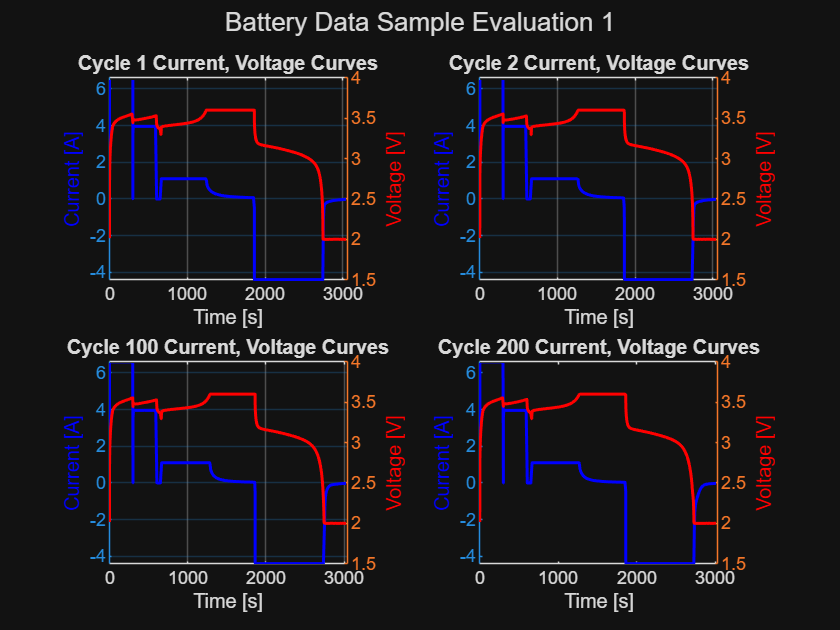


% STEP 1b (Optional)
% Battery data sample evaluation: observing differences in the charging cycles over
% a select sample of cycles (just for team reference, this is not part of
% the task requirements/steps.

% multi-subplot generation to compare cycles 1, 2, 100, 200, 300, 400, 500, 600, 700, 800, 875, and 876
sample_cycles_set1 = [1, 2, 100, 200];
sample_cycles_set2 = 300:100:600;
sample_cycles_set3 = [700, 800, 875, 876];

%creating a window for the subplots to appear
figure;

%starting a loop for the amount of cycles stored sample cycles in set 1
for index = 1:length(sample_cycles_set1)
grid on;

%plotting a 2x2 subplot (index 1 = top left, index 2 is top right...)
subplot(2, 2, index)

%selecting only the rows that belong to that cycle and setting time = 0
cycleData = data(data.Cycle_Index == sample_cycles_set1(index), :);
cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1));

%activating the left side of the y axis and changing the axes color to blue
%to signify current 
yyaxis left;
gca.YColor = 'blue';

%plotting the current (color: blue)
plot(cycleData.DateTime,cycleData.Current, '-b', 'LineWidth', 1.5);

%labeling the y axis
ylabel('Current [A]', 'Color', 'blue');

%switching to the right side of the y-axis and changing the color to red to
%signify it is for voltage
yyaxis right;
gca.YColor = 'red';

%plotting the Voltage on the same graph (color: red) and labeling the axis
plot(cycleData.DateTime,cycleData.Voltage, '-r', 'LineWidth', 1.5);
ylabel('Voltage [V]', 'Color', 'red');

%labeling the x axis, titling each of the graphs, titling the main subplot,
%and ending the loop
xlabel("Time [s]");
title(sprintf('Cycle %d Current, Voltage Curves', sample_cycles_set1(index)))
sgtitle("Battery Data Sample Evaluation 1")
end

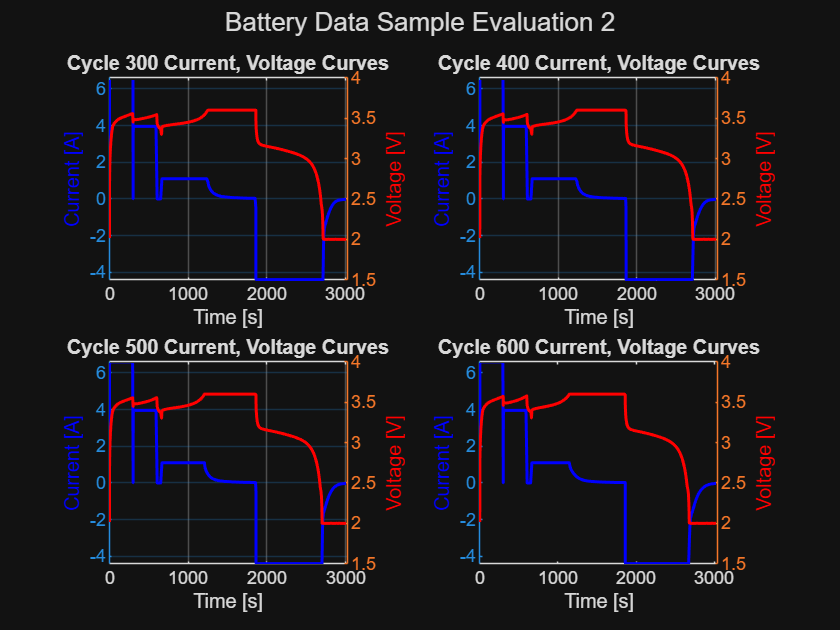

%repeating the same steps as above, instead for Battery Data Sample
%Evaluation 2, which include cycles 300, 400, 500, 600
figure;
for index = 1:length(sample_cycles_set2)
grid on;
subplot(2, 2, index)
cycleData = data(data.Cycle_Index == sample_cycles_set2(index), :);
cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1));
yyaxis left;
gca.YColor = 'blue';
plot(cycleData.DateTime,cycleData.Current, '-b', 'LineWidth', 1.5);
ylabel('Current [A]', 'Color', 'blue');
yyaxis right;
gca.YColor = 'red';
plot(cycleData.DateTime,cycleData.Voltage, '-r', 'LineWidth', 1.5);
ylabel('Voltage [V]', 'Color', 'red');
xlabel("Time [s]");
title(sprintf('Cycle %d Current, Voltage Curves', sample_cycles_set2(index)))
sgtitle("Battery Data Sample Evaluation 2")
end

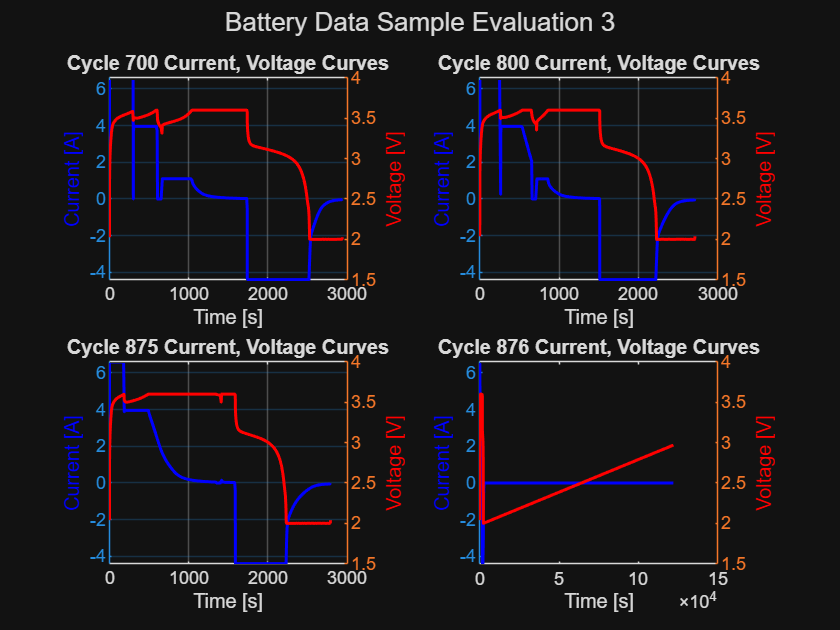

%repeating the same steps as above, instead for Battery Data Sample
%Evaluation 2, which include cycles 700, 800, 875, 876
figure;
for index = 1:length(sample_cycles_set3)
grid on;
subplot(2, 2, index)
cycleData = data(data.Cycle_Index == sample_cycles_set3(index), :);
cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1));
yyaxis left;
gca.YColor = 'blue';
plot(cycleData.DateTime,cycleData.Current, '-b', 'LineWidth', 1.5);
ylabel('Current [A]', 'Color', 'blue');
yyaxis right;
gca.YColor = 'red';
plot(cycleData.DateTime,cycleData.Voltage, '-r', 'LineWidth', 1.5);
ylabel('Voltage [V]', 'Color', 'red');
xlabel("Time [s]");
title(sprintf('Cycle %d Current, Voltage Curves', sample_cycles_set3(index)))
sgtitle("Battery Data Sample Evaluation 3")
end

% NOTE: the charging-discharging cycles start to degrade near the end...
% choosing CYCLE 1 for the next part because it doesn't have as many...
% discontinuities/gaps as some of the other randomly sampled cycle graphs.

% After viewing the example charging cycles above, select any cycle to fit.
% Valid cycle numbers are integers 1 through 876.

selectedCycle = input( ...
    'Enter the charging cycle to analyze (1-876): ');

% Keep asking until a valid cycle number is entered
while ~(isscalar(selectedCycle) && ...
        selectedCycle >= 1 && ...
        selectedCycle <= 876 && ...
        mod(selectedCycle,1)==0)

    fprintf('Invalid selection.\n');
    selectedCycle = input( ...
        'Please enter an integer from 1 to 876: ');
end

fprintf('Using Cycle %d.\n\n', selectedCycle);

Using Cycle 1.





% STEP 2
% Pre-process the data to focus on a single cycle, and the period of time
% within that cycle that the battery was being charged

% Single cycle to focus on: CYCLE 1, code below is just from following the...
% 'MathWorks example Li-ion batteries data' (parsing the data)
bParser = batteryTestDataParser(data);
bParser.CurrentVariable = 'Current';
bParser.VoltageVariable= "Voltage";
bParser.TimeVariable = "DateTime";
bParser.CycleIndexVariable = 'Cycle_Index';
bParser.StepIndexVariable = 'Step_Index';

% generate table formatting (for segmented data)
segmentedRawDataTable = segmentData(bParser);
head(segmentedRawDataTable,5)

    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature    CyclingModes    CyclingPhases    IsValid
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    <s

%measurements over one cycle

% checking data type, data values
data(data.Cycle_Index == 1, :)

ans = 1078×15 table
    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    ___________    ___________________    



% STEP 3
% Follow the provided workflow to fit the voltage equation to your selected
% data.
% HINT: Vmax is known, so the only unknown in the equation is RC (also
% known as tau, the RC time constant - it is equivalent to the time it takes
% for a capacitor to reach ~63.2% of its max voltage).
% When you are fitting the curve to the data, you are essentially estimating
% the unknown parameter, tau.

% All the stuff below is just parsing the data to CONFIRM that Vmax ~= 3.6 Volts
% verify what variable 'dV/dt' is actually called
data.Properties.VariableNames

ans = 1×15 cell array
    {'Data_Point'}    {'Test_Time'}    {'DateTime'}    {'Step_Time'}    {'Step_Index'}    {'Cycle_Index'}    {'Current'}    {'Voltage'}    {'Charge_Capacity'}    {'Discharge_Capacity'}    {'Charge_Energy'}    {'Discharge_Energy'}    {'dV/dt'}    {'Internal_Resistance'}    {'Temperature'}



% change var name of "dV/dt" because it isn't syntax-friendly to
% MATLAB ("data.dV/dt" keeps giving error")
data = renamevars(data, "dV/dt", "dVdt");

% boolean array of where dV/dt ~= 0, only in region of Vmax, only for cycle
% 1
mask = data.Cycle_Index == selectedCycle & data.Voltage > 3.2 & abs(data.dVdt) < 0.01;

% use boolean array to analyze that flat region near the theoretical Vmax,
% in "Cycle 1 Current, Voltage Curves" graph
V_maxes_ls = data.Voltage(mask);

% temporarily displayed command: 'disp(Vmaxes_ls)', which is a list of Vmaxes
experimental_V_max = max(V_maxes_ls);

% just verifying if experimental_V_max is close to V_max = 3.6 Volts
fprintf("Experimental Voltage Maximum: %.5f V\n", experimental_V_max)

Experimental Voltage Maximum: 3.60043 V



% checking data type, data values
data(data.Cycle_Index == selectedCycle, :)

ans = 1078×15 table
    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dVdt        Internal_Resistance    Temperature
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    ___________    ___________________    

charging_data_only = data(data.Cycle_Index == selectedCycle & data.Current >= 0, :);


% variables / parameters of (custom) fitting equation
t = seconds(charging_data_only.DateTime - charging_data_only.DateTime(1));
V = charging_data_only.Voltage;
V_max = max(V);

% "optimization" of tau value?
model1 = @(T, t) V_max * (1 - exp(-t / T));

% placeholder guess for tau (T)
T0 = 1000;
T = lsqcurvefit(model1, T0, t, V);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


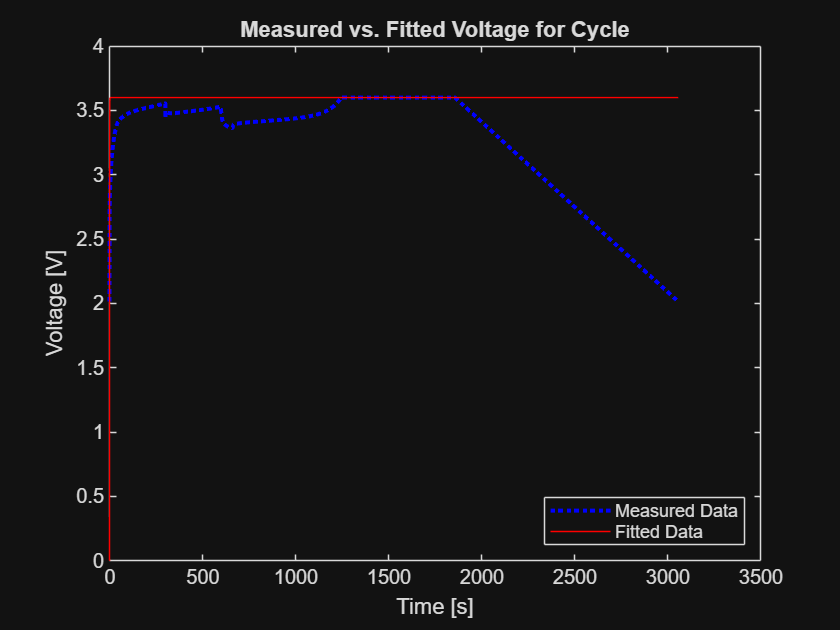


V_fit = model1(T, t);

% STEP 4
% Plot the data and the fitted curve in the same figure.
% Using curve fitter! 't' is time (x-axis), 'V' is Voltage (y-axis), ...
% V_max is given 3.6 value.
% 'T' will be used to represent tau, the RC time constant (T = RC)

% plotting both parsed data AND fitted data
figure
plot(t, V, 'b', 'LineWidth', 2, 'LineStyle', ':')
hold on
plot(t, V_fit, 'r')

% final graph labels + legend
xlabel('Time [s]')
ylabel('Voltage [V]')
title('Measured vs. Fitted Voltage for Cycle')
legend('Measured Data', 'Fitted Data', 'Location', 'southeast')

fprintf("tau = %.4f seconds\n", T)

tau = 0.3872 seconds


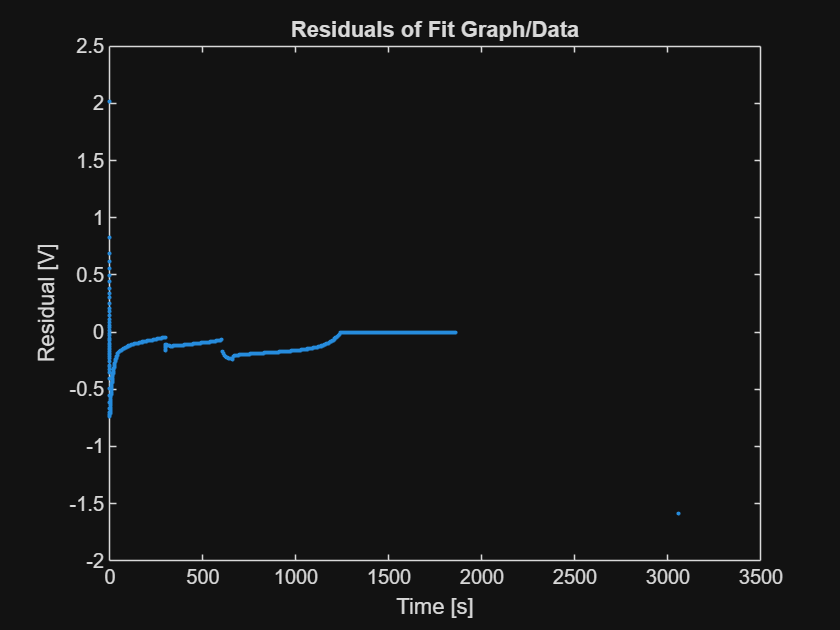


% STEP 5
% Calc + display the goodness-of-fit statistics.
residuals = V - V_fit;

sum_of_squared_errors = sum(residuals.^2);

root_mean_squared_error = sqrt(mean(residuals.^2));

% next, use 'sum_of_squared_errors' and calc 'total sum of squares'
% to get R^2 (common statistical value)
total_sum_of_squares = sum((V - mean(V)).^2);

R2_value = 1 - sum_of_squared_errors / total_sum_of_squares;

% calculate the number of data points
n = length(V);

% this is the number of fitted parameters (tau)
p = 1;

% calculating degrees of freedom
dfe = n - p;

% calculating the adjusted r square
adj_R2 = 1 - (1 - R2_value) * ((n - 1) / dfe);

% Plotting the residuals for visual purposes
figure
grid on
plot(t, residuals, '.')
xlabel('Time [s]')
ylabel('Residual [V]')
title('Residuals of Fit Graph/Data')


% easy display statements
fprintf("Residuals:")

Residuals:

disp("Residuals:")

Residuals:


disp(residuals);

    2.0153
    0.8274
    0.6877
    0.6134
    0.5576
    0.4936
    0.4389
    0.3834
    0.3384
    0.3027
    0.2488
    0.2059
    0.1786
    0.1485
    0.1129
    0.0831
    0.0590
    0.0370
    0.0097
   -0.0130
   -0.0308
   -0.0534
   -0.0614
   -0.0764
   -0.0958
   -0.1104
   -0.1259
   -0.1443
   -0.1526
   -0.1701
   -0.1848
   -0.2002
   -0.2180
   -0.2283
   -0.2591
   -0.2896
   -0.3012
   -0.3291
   -0.3539
   -0.4071
   -0.4938
   -0.5579
   -0.6166
   -0.6663
   -0.7017
   -0.7229
   -0.7354
   -0.7408
   -0.7410
   -0.7371
   -0.7312
   -0.7239
   -0.7239
   -0.7155
   -0.7063
   -0.6968
   -0.6869
   -0.6768
   -0.6668
   -0.6565
   -0.6463
   -0.6363
   -0.6262
   -0.6162
   -0.6162
   -0.6062
   -0.5960
   -0.5857
   -0.5753
   -0.5652
   -0.5547
   -0.5447
   -0.5346
   -0.5243
   -0.5142
   -0.5040
   -0.4936
   -0.4836
   -0.4735
   -0.4633
   -0.4529
   -0.4427
   -0.4326
   -0.4326
   -0.4224
   -0.4123
   -0.4022
   -0.3922
   -0.3922
   -0.3821
   -0.3721

disp("Goodness of Fit Statistics")

Goodness of Fit Statistics


fprintf("Sum of Squared Errors (SSE): %.4f V^2\n", sum_of_squared_errors)

Sum of Squared Errors (SSE): 36.6372 V^2


fprintf("Root Mean Squared Error (RMSE): %.4f V \n", root_mean_squared_error)

Root Mean Squared Error (RMSE): 0.2402 V 


fprintf("R^2 Value: %.4f \n", R2_value)

R^2 Value: 0.4187 


fprintf("Degrees of Freedom (DFE): %.2f \n", dfe)

Degrees of Freedom (DFE): 634.00 


fprintf("Adjusted R^2 Value: %.4f \n", adj_R2)

Adjusted R^2 Value: 0.4187 


fprintf("Tau = %.4f s\n", T)

Tau = 0.3872 s


## Task 2: Plot the electrical terms that express how energy moves in a circuit

To visualize the battery's charging policy, write code to visualize the current, voltage, and power measurements for one charging cycle. Present the visualization as one figure with three subplots, one each for:

- Voltage vs. time

- Current vs. time

- Power vs. time

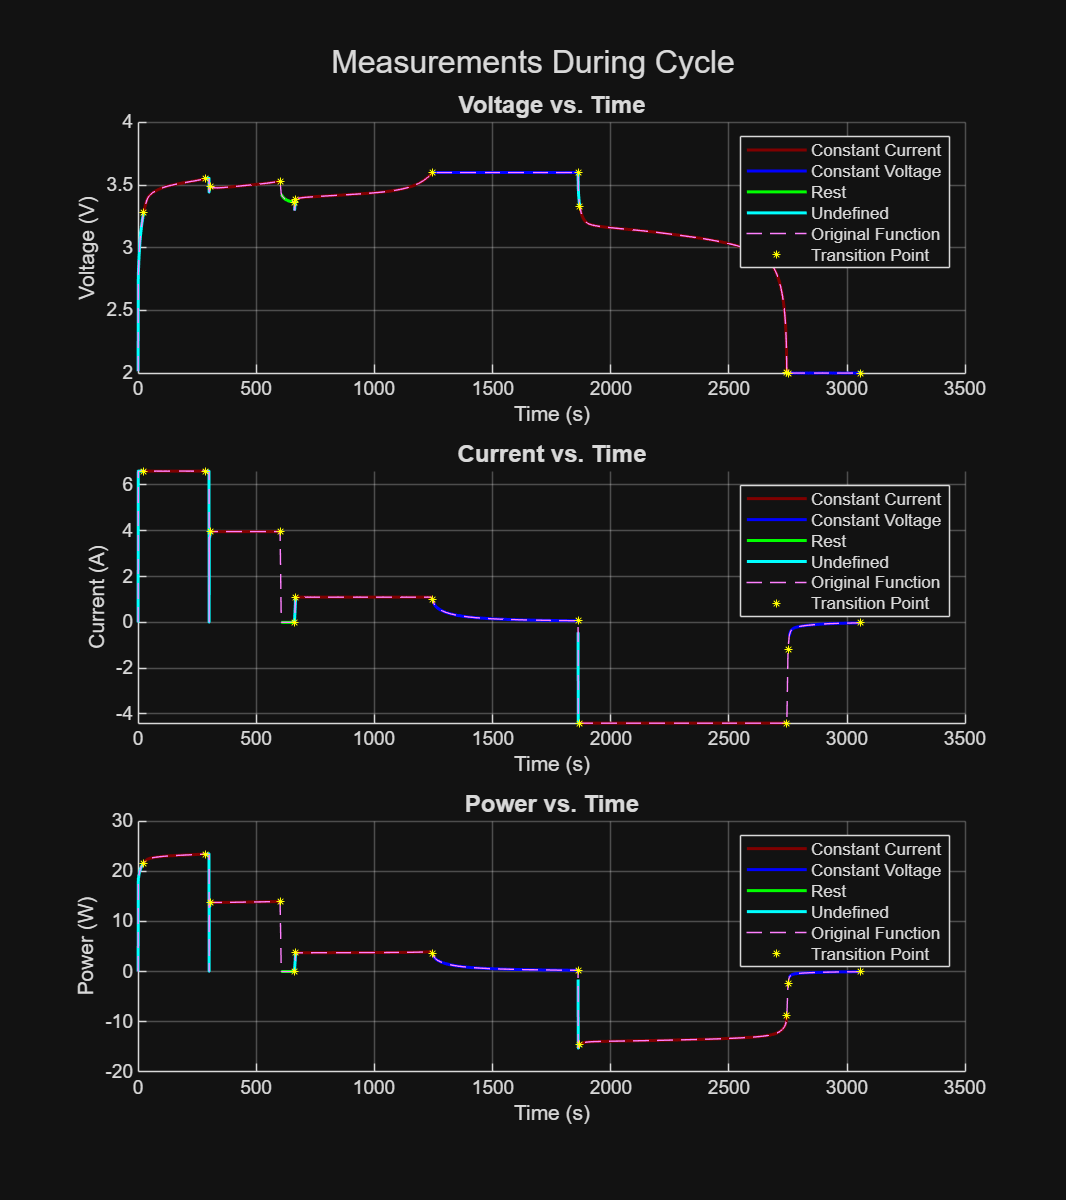

% Insert your code in the spaces below (or make use of helper functions and
% indicate where they can be found). Ensure your code is well-documented.

% STEP 1
% Create a figure handle and initialize the first subplot. Plot voltage vs.
% time.

%the cycle I will be focusing on (has been the standard so far)
cycle_number = selectedCycle;

%getting only the segmented data for the chosen cycle
cycle_data = segmentedRawDataTable(segmentedRawDataTable.Cycle_Index == cycle_number,:);

%resets time so the cycle data starts at the 0 second mark
cycle_data.DateTime = seconds(cycle_data.DateTime - cycle_data.DateTime(1));

%defining variables to make them easier to input
time = cycle_data.DateTime;
current = cycle_data.Current;
voltage = cycle_data.Voltage;

%creating figure (position adjusts the size of the graphs (larger) so they
%are able to be viewed clearly)
figure_handle = figure('Name', 'Battery Charging Profile', 'Position', [200,100,800,900]);
 
%creating a 3 row by 1 column matrix for each of the graphs
% (Voltage v time, Current v time, and power v time, 
% this one is first subplot indicated by the third 

subplot(3, 1, 1) 

%importing from the helper function(CycleModes) so we don't have to keep
%rewriting the same function over again
plotcycle_modes(time, voltage, cycle_data.CyclingModes) 

%also plotting the original function for Voltage v time on the same graph
%(under it where it is black and dotted line) (idk if this is needed)
hold on
plot(time, voltage,'Color', [1 0.5 1], 'LineStyle','--', 'DisplayName','Original Function')
hold off

%plotting transition points
plotTransition_points(time, voltage, cycle_data.CyclingModes)

%titling the first subplot
title('Voltage vs. Time', 'FontSize', 12)
xlabel('Time (s)')
ylabel('Voltage (V)')


% STEP 2
% Use a second subplot to plot current vs. time.

%repeating the same steps as done in step 1
subplot(3,1,2)
plotcycle_modes(time, current, cycle_data.CyclingModes)

hold on
plot(time, current,'Color', [1 0.5 1], 'LineStyle','--', 'DisplayName','Original Function')
hold off

plotTransition_points(time, current, cycle_data.CyclingModes)

title('Current vs. Time', 'FontSize', 12)
xlabel('Time (s)')
ylabel('Current (A)')

% STEP 3
% Use a third subplot to plot power vs time.
% Hint: P = I * V where I is current in amps. You will first
% need to compute power before you can create this plot.

% Calculating power using P=IV (Use . since multiplying rows in matrix)
power = current .*voltage;

% Repeat similar code to Steps 1 & 2 to plot power vs time using the helper
% function created

subplot(3,1,3)
plotcycle_modes(time, power, cycle_data.CyclingModes)

hold on
plot(time, power,'Color', [1 0.5 1], 'LineStyle','--', 'DisplayName','Original Function')
hold off

plotTransition_points(time, power, cycle_data.CyclingModes)

title('Power vs. Time', 'FontSize', 12)
xlabel('Time (s)')
ylabel('Power (W)')
sgtitle('Measurements During Cycle', 'FontSize', 16)


%Separating the different phases (CC, CV, Undefined, Rest) as it is
%applicable later

CC = cycle_data.CyclingModes == "CC";
CV = cycle_data.CyclingModes == "CV";
Rest = cycle_data.CyclingModes == "Rest";
Undefined = cycle_data.CyclingModes == "Undefined";



## Task 3: Compute analytical results

To get started on using MATLAB for numerical integration and differentiation, start with this [doc page](https://www.mathworks.com/help/matlab/numerical-integration-and-differentiation.html?s_tid=CRUX_lftnav).

- Conduct a rate-of-change analysis by computing the derivative at key intervals in the voltage data

- Compute the time required to reach 80% and 100% charge

- Compute the total energy delivered to the battery by using integration to calculate the area under the power-time curve.

- Estimate the resistive energy loss

- Save the results to a summary table.

% Insert your code in the spaces below (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented.

% STEP 1: Compute the rate of voltage change at different key time
% intervals. This helps you mathematically characterize the battery's
% charging profile and is more reliable than simply eyeballing the voltage
% vs. time plot. 
% Optional: plot the points of notable transitions in charging dynamics in
% the voltage vs. time plot generated above
% Hint: explore using the gradient function

% Calculating the derivative of voltage with respect to time (dV/dt) using
% the gradient function
dVdt = gradient(voltage,time);

% Creating a table with some of the important stats
beginning_dVdt = dVdt(1);
middle_dVdt = dVdt(round(end/2));
end_dVdt = dVdt(end);
[maximum_dVdt, maxIndex] = max(dVdt);
maxTime = time(maxIndex);
[minimum_dVdt, minIndex] = min(dVdt);
minTime = time(minIndex);

Overview = table(beginning_dVdt, middle_dVdt, end_dVdt, maximum_dVdt, maxTime, minimum_dVdt, minTime)

Overview = 1×7 table
    beginning_dVdt    middle_dVdt    end_dVdt    maximum_dVdt    maxTime    minimum_dVdt    minTime
    ______________    ___________    ________    ____________    _______    ____________    _______

       0.10933        -1.2401e-06    0.011871       1.9047       0.4699       -0.48618      2744.9 


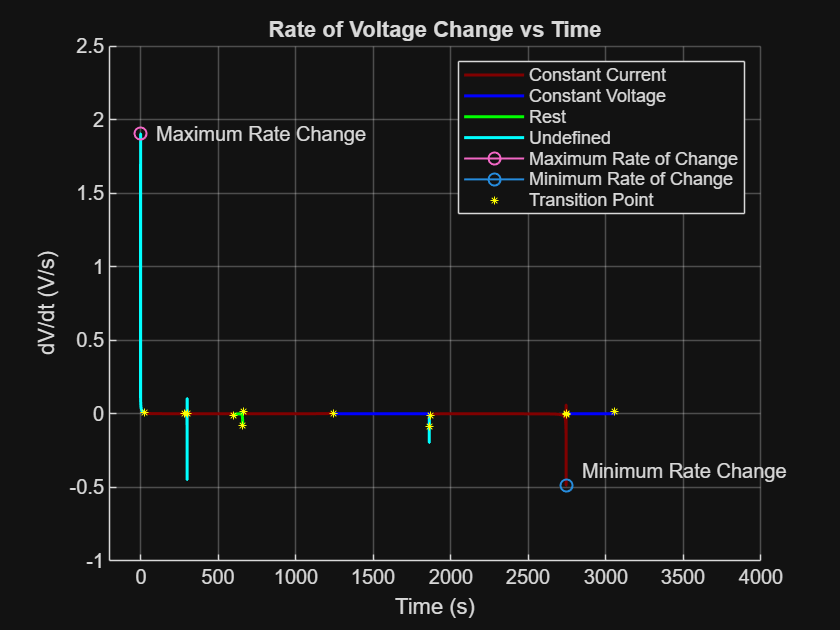


% Plot the data using the same plotting methods as before
figure
plotcycle_modes(time, dVdt, cycle_data.CyclingModes)
title("Rate of Voltage Change vs Time")
xlabel("Time (s)")
ylabel("dV/dt (V/s)")
xlim([-200 4000]); ylim([-1 2.5])
grid on
hold on

% Included max and min points for visualization

% (OPTIONAL: Identify charging spaces in regions and split to CC and CV region.
% (also did Rest and Undefined))
plot(maxTime, maximum_dVdt,'-o', 'LineWidth', 1, 'DisplayName','Maximum Rate of Change')
text(maxTime + 100, maximum_dVdt, 'Maximum Rate Change')
plot(minTime, minimum_dVdt,'-o', 'LineWidth', 1, 'DisplayName','Minimum Rate of Change')
text(minTime + 100, minimum_dVdt + 0.1, 'Minimum Rate Change')
plotTransition_points(time, dVdt, cycle_data.CyclingModes)

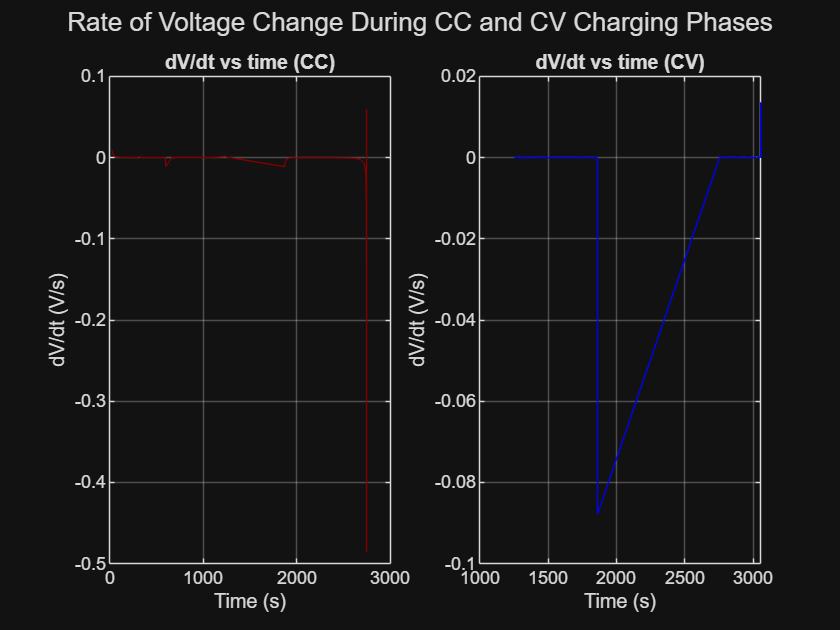

%Creating and displaying voltage derivatives calculated in important time
%intervals


%Optional: Splitting the CC and the CV (apart of Step 1)

figure 

subplot(1,2,1)

%time(CC) and dVdt(CC) make sure to only take in account for the CC
%datasets
plot(time(CC), dVdt(CC), 'Color', [.5, 0, 0]) %same shade of red as before for consistency
title("dV/dt vs time (CC)")
xlabel("Time (s)")
ylabel("dV/dt (V/s)")
grid on

subplot(1,2,2)
plot(time(CV), dVdt(CV), 'b')
title("dV/dt vs time (CV)")
xlabel("Time (s)")
ylabel("dV/dt (V/s)")
grid on

sgtitle("Rate of Voltage Change During CC and CV Charging Phases") %main title


%confirming if the beginning dV/dt is roughly 0 by using an if/else loop
if fix(dVdt(find(CV, 1, 'first'))) == 0   %nested function to make sure that the CV is rounded down for accuracy
    fprintf('The rate of voltage change analysis is confirmed: The beggining of dV/dt for CV = 0')
else 
    fprintf('The rate of voltage change analysis is not confirmed')
end

The rate of voltage change analysis is confirmed: The beggining of dV/dt for CV = 0


% STEP 2: Compute the time required to reach charge and 100% charge

% Max voltage threshold for full charge (3.6 V based on dataset)
V_max = max(voltage); %max voltage
V_80 = 0.80 * V_max; % 80% of max voltage

%calculating the time to reach 80% charge
idx_80 = find(voltage >= V_80, 1); %finds where .8*max(V) occurs
time_80 = time(idx_80); %determines the time at 80%

%finding where 100% charge is first reached
idx_100 = find(voltage == V_max, 1);
time_100 = time(idx_100);

% Display the results
fprintf('Time to reach 80%% charge (%.2f V): %.2f seconds\n', V_80, time_80);

Time to reach 80% charge (2.88 V): 2.84 seconds


fprintf('Time to reach 100%% charge (%.2f V): %.2f seconds\n', voltage(idx_100), time_100);

Time to reach 100% charge (3.60 V): 1246.65 seconds



%2b

%User can enter their desired percentage (0-100) and find out amount of
%charge it takes to get there

%prompting the user to enter their desired charge percentage
percent = input('Enter your desired charge percentage (0-100): ');

%using an if else loop to calculate the amount of charge if the percent
%entered is from (0-100)
if percent >= 0 && percent <= 100
    V_perc = V_max * (percent/100); % formula to calculate voltage value when percentage is received
    idx = find(voltage >= V_perc,1)
    charging_time = time(idx)

    fprintf("Time to reach %d%% charge: %.4f s\n", percent, charging_time)
else
    fprintf("Enter value from 0-100") %occurs when value from 0-100 is not entered
end

idx = 1

charging_time = 0

Time to reach 33% charge: 0.0000 s



% STEP 3: Use integration to calculate the area under the power-time curve.
% This represents the total energy delivered to the battery during charging.
% Hint: explore using the trapz function

%power has already been calculated above in task 2 step 3 (the first line of
%code)

% integrating to find energy using the formula E = int(P)dt 

total_energy_joules = trapz(time, power); %first calculating total energy in J

%converting energy to kJ (first) and Watt-hours (second) to display
total_energy_kJ = total_energy_joules / 1000;
total_energy_Wh = total_energy_joules / 3600;

% Displaying final results
fprintf('Total Energy Delivered: %.2f Joules\n', total_energy_joules);

Total Energy Delivered: 1690.79 Joules


fprintf('Total Energy Delivered: %.2f kJ (%.4f Wh)\n', total_energy_kJ, total_energy_Wh);

Total Energy Delivered: 1.69 kJ (0.4697 Wh)


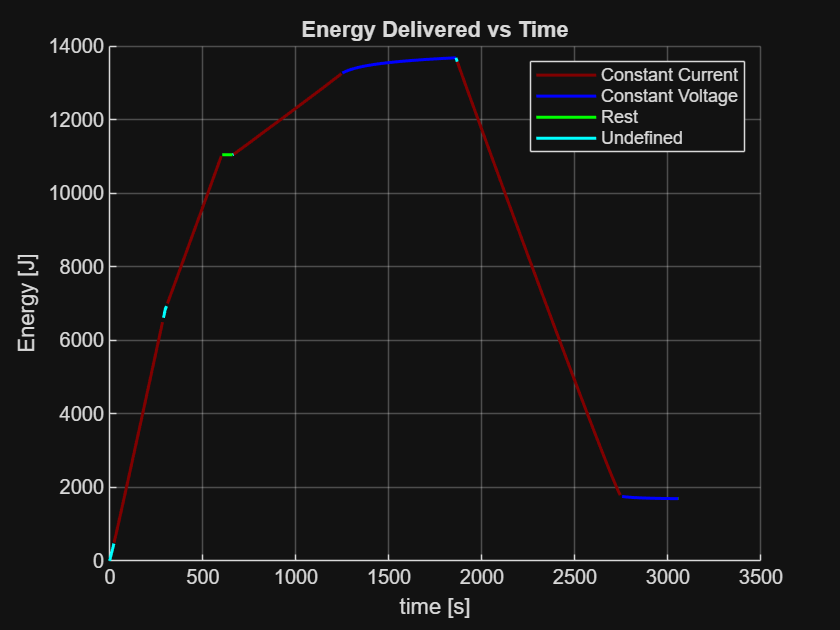


%3b Plotting Energy vs time graph

%calculating energy in vector form (using cumtrapz rather than trapz)
energy = cumtrapz(time,power);

figure
plotcycle_modes(time, energy, cycle_data.CyclingModes)

title('Energy Delivered vs Time')
xlabel('time [s]')
ylabel('Energy [J]')


% STEP 4: Estimate the Resistive energy loss. 
% Hint: use Joule's heating formula (P = I^2 * R) to estimate power loss in
% watts. The energy loss is given as E = P * t, where t is time in seconds
% and energy is in joules.

resistance = cycle_data.Internal_Resistance;

%Calculating power loss as requested
Power_loss = (current.^2) .*resistance;

%Calculating energy loss as requested
E_loss = Power_loss.*time;

%calculating Energy loss (total) for later 
E_loss_tot = trapz(time, Power_loss);

%Calculating energy using the power calculated before (P=IV) to compare to
%the power loss
Energy = power.*time;

%Adding power (P = IV) (calculated previously) to compare to power loss in
%table
Comparisons = table(time, power, Power_loss, Energy, E_loss)

Comparisons = 1078×5 table
     time      power     Power_loss    Energy       E_loss  
    ______    _______    __________    _______    __________

         0          0            0           0             0
    0.1578    0.80013    0.0027326     0.12626    0.00043121
    0.1843     1.3504     0.007642     0.24887     0.0014084
    0.1994     1.6301     0.011015     0.32505     0.0021965
    0.2132     2.0593     0.017252     0.43905     0.0036781
    0.2281     2.3481     0.022123     0.53561     0.0050463
    0.2419     2.6443     0.027651     0.63967     0.0066889
    0.2566     2.9464     0.033806     0.75604     0.0086746
    0.2698     3.2513     0.040507     0.87719      0.010929
    0.2836     3.7226     0.051786      1.0557      0.014686
    0.3002     4.0429     0.060044      1.2137      0.018025
     0.31

%calculating and displaying average power & energy loss

avg_P_loss = mean(Power_loss);
avg_E_loss = mean(E_loss);

fprintf('Average Power Loss = %.4f W\n', avg_P_loss)

Average Power Loss = 0.2473 W


fprintf('Average Energy Loss = %.4f J\n', avg_E_loss)

Average Energy Loss = 280.6738 J


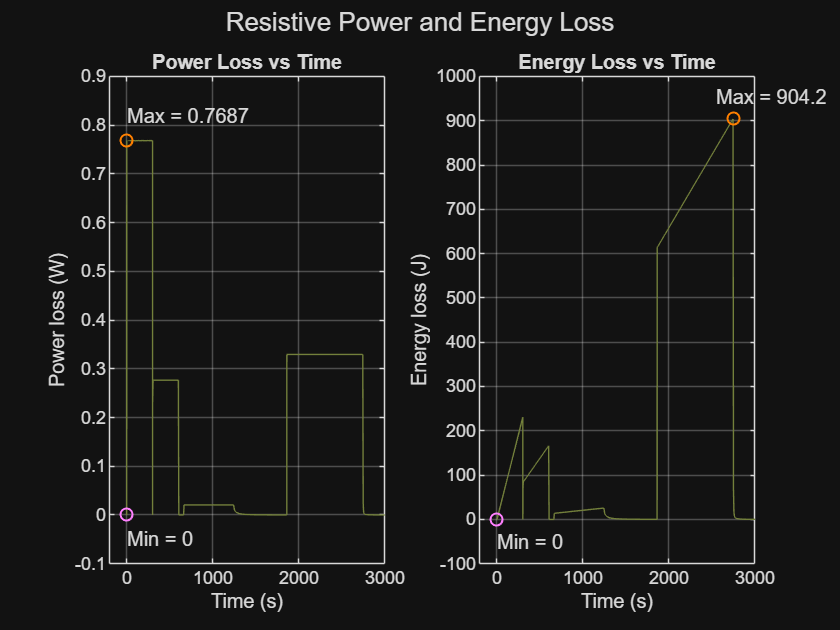


%4b: Depicting power and energy loss as a function of time.

%Plotting power loss vs time and resistance loss vs time graphs and as well
%as taking note of their maximum and minimum values for visual purposes

[max_P_loss, max_Idx] = max(Power_loss); 
max_time = time(max_Idx); 

[min_P_loss, min_Idx] = min(Power_loss); 
min_time = time(min_Idx); 


[max_E_loss, max_idx] = max(E_loss); 
max_Time = time(max_idx); 

[min_E_loss, min_idx] = min(E_loss); 
min_Time = time(min_idx); 


%plotting... 
figure 

%power loss vs time 
subplot(1,2,1) 
plot(time, Power_loss,'Color', [.45,.5,.23]) 

hold on 
plot(max_time, max_P_loss,'-o', 'LineWidth', 1, 'Color', [1 0.5 0]) 
text(max_time, max_P_loss +.05, ['Max = ', num2str(round(max_P_loss,4))]) 

plot(min_time, min_P_loss, '-o', 'LineWidth', 1, 'Color', [1 0.5 1]) 
text(min_time, min_P_loss -.05, ['Min = ', num2str(min_P_loss)]) 
hold off 

xlim([-200,3000]); ylim([-.1,.9])
title("Power Loss vs Time")
xlabel("Time (s)") 
ylabel("Power loss (W)") 
grid on 

%energy loss vs time 
subplot(1,2,2) 
plot(time, E_loss, 'Color', [.45,.5,.23]) 

hold on 
plot(max_Time, max_E_loss,'-o', 'LineWidth', 1, 'Color', [1 0.5 0]) 
text(max_Time - 200, max_E_loss + 50, ['Max = ', num2str(round(max_E_loss,1))]) 

plot(min_Time, min_E_loss, '-o', 'LineWidth', 1, 'Color', [1 0.5 1])
 text(min_Time, min_E_loss -50, ['Min = ', num2str(min_E_loss)]) 
hold off 

xlim([-200,3000]); ylim([-100,1000])
title("Energy Loss vs Time") 
xlabel("Time (s)") 
ylabel("Energy loss (J)") 
sgtitle("Resistive Power and Energy Loss")
grid on 


% STEP 5: Save results to a summary table. Display the table.
%displaying only the required items and not the optional ones

summary_task1 = table(T, sum_of_squared_errors, root_mean_squared_error, R2_value, dfe, adj_R2,... 
    'VariableNames', {'Tau (s)', 'Sum of the squared errors', 'root of the mean squared error', 'R^2', ...
    'Degrees of Freedom', 'Adjusted R^2 Value'});

%no values required for display in task 2

summary_task3 = table(beginning_dVdt, middle_dVdt, end_dVdt, time_80, time_100, ... 
    total_energy_joules, E_loss_tot, 'VariableNames', ... 
    {'Beginning dV/dt value (V/s)', 'Middle dV/dt value (V/s)', 'Final dV/dt value (V/s)', ... 
    'Time to 80% charge (s)', 'Time to 100% charge (s)', 'Total Energy (J)', 'Resistive Energy Loss (J)'});
disp("Task 1 Summary:")

Task 1 Summary:


disp(summary_task1) 

    Tau (s)    Sum of the squared errors    root of the mean squared error      R^2      Degrees of Freedom    Adjusted R^2 Value
    _______    _________________________    ______________________________    _______    __________________    __________________

    0.38719             36.637                          0.2402                0.41872           634                 0.41872      



disp("No values required to display for Task 2 summary (graphs)")

No values required to display for Task 2 summary (graphs)



disp("Task 3 Summary:")

Task 3 Summary:


disp(summary_task3)

    Beginning dV/dt value (V/s)    Middle dV/dt value (V/s)    Final dV/dt value (V/s)    Time to 80% charge (s)    Time to 100% charge (s)    Total Energy (J)    Resistive Energy Loss (J)
    ___________________________    ________________________    _______________________    ______________________    _______________________    ________________    _________________________

              0.10933                    -1.2401e-06                  0.011871                    2.8401                    1246.7                  1690.8                   618.4          



## Optional: 

In this portion...

- Utilize the data from one cycle. 

- Identify the charging phases in the dataset and split the data into two regions: CC region (where voltage is increasing and current is approximately constant) and CV region (constant voltage, decreasing current). Clearly mark the transition points on plots. 

- Optionally, confirm using rate of voltage change analysis (the derivative should be 0 at the start of the CV phase).

- Analyze each phase separately. 

- Fit the same exponential model as above to the CC phase and fit an exponential decay model to the plot of current vs. time during the CV phase.

- Compare power vs. time during each phase and compute total energy delivered during each phase. 

- Identify when charging is most efficient and when most energy is delivered.

- CC-CV is one type of charging profile. Use Simscape Battery to model and compare different charging profiles (such as constant current, multi-stage/smart charging, or fast electric vehicle charging). 

- Plot the simulation results (charging/discharging current, battery voltage, and battery temperature) for different charging profiles. 

%Step 1
%identify and split the charging regions into CC and CV while marking the
%transition points


here

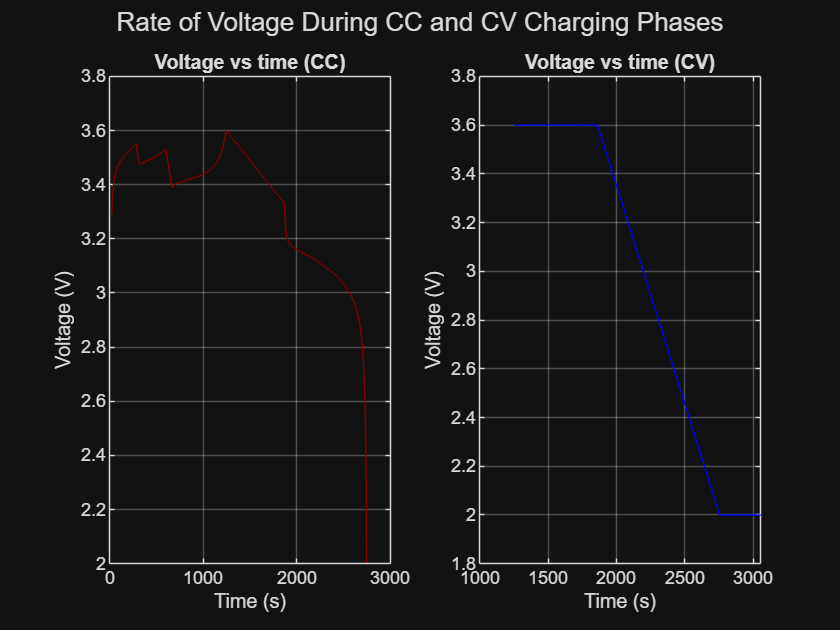

% this linked section includes the identification of the charging phases through
% transition points and distinct colors, which covers a portion of step 1.
% The different colors used throughout the plots represent the different
% phases (CC,CV,Rest, and Undefined), while the transition points are
% depicted using yellow stars.


%Step 2: Analyze each phase separately. Fit the same exponential 
% model as above to the CC phase and fit an exponential decay model 
% to the plot of current vs. time during the CV phase.

%Analyzing both the CC and CV phases separately (plotting them)
figure

%first voltage vs time
subplot(1,2,1)
plot(time(CC), voltage(CC), 'Color', [.5, 0, 0])
title("Voltage vs time (CC)")
xlabel("Time (s)")
ylabel("Voltage (V)")
grid on

subplot(1,2,2)
plot(time(CV), voltage(CV), 'b')
title("Voltage vs time (CV)")
xlabel("Time (s)")
ylabel("Voltage (V)")
grid on
sgtitle("Rate of Voltage During CC and CV Charging Phases") %main title

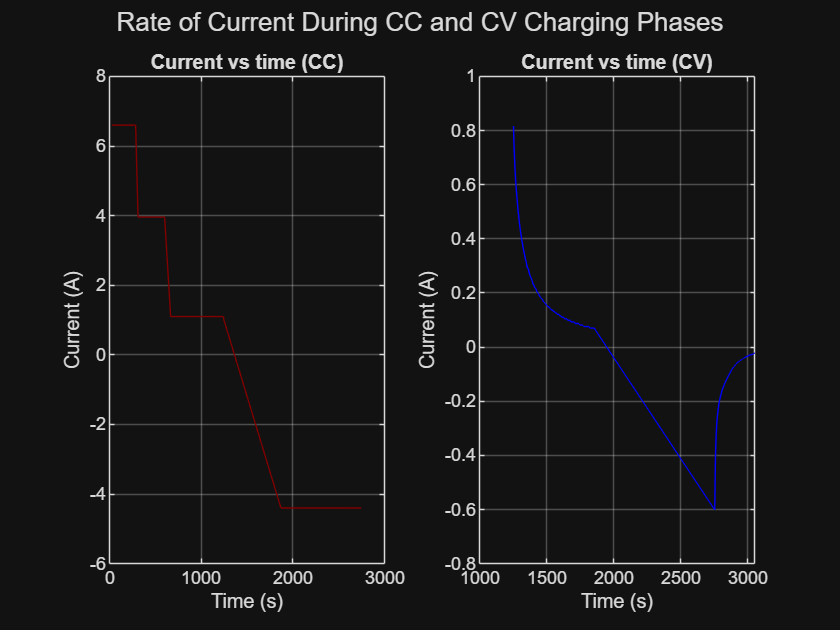


%next current vs time
figure
subplot(1,2,1)
plot(time(CC), current(CC), 'Color', [.5, 0, 0])
title("Current vs time (CC)")
xlabel("Time (s)")
ylabel("Current (A)")
grid on

subplot(1,2,2)
plot(time(CV), current(CV), 'b')
title("Current vs time (CV)")
xlabel("Time (s)")
ylabel("Current (A)")
grid on

sgtitle("Rate of Current During CC and CV Charging Phases") %main title

%fitting the exponential model to the CC voltage

%making the time start at t = 0
time_CC = time(CC) - time(find(CC,1,'first'));

%using the model1 from before since it doesn't change as well as the
%tau_naught value

% writing in terms of the CC
T_CC = lsqcurvefit(model1, T0, time_CC, voltage(CC));


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


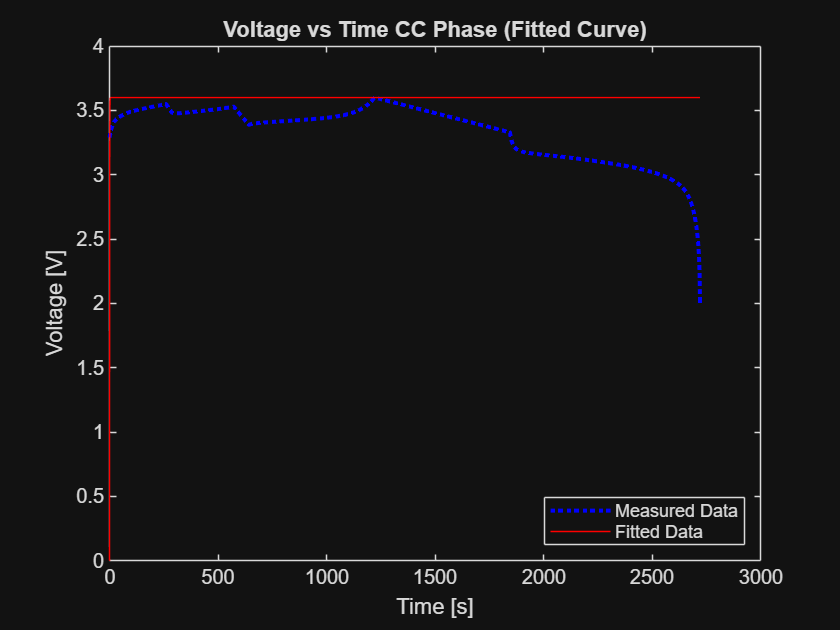


%calculating the fitted voltage for CC
V_fit_CC = model1(T_CC, time_CC);

% plotting both parsed data AND fitted data
figure
plot(time_CC, voltage(CC), 'b', 'LineWidth', 2, 'LineStyle', ':')
hold on
plot(time_CC, V_fit_CC, 'r')

% final graph labels + legend
xlabel('Time [s]')
ylabel('Voltage [V]')
title('Voltage vs Time CC Phase (Fitted Curve)')
legend('Measured Data', 'Fitted Data', 'Location', 'southeast')

fprintf("CC phase tau = %.2f seconds\n", T_CC)

CC phase tau = 0.49 seconds



%fitting the exponential decay model to CV
%defining current
I = charging_data_only.Current;

%setting the time at t = 0
time_CV = time(CV);
time_CV = time_CV - time_CV(1);

% Initial guesses for starting current (keeping tau the same)
current_CV = current(CV);
I0 = current_CV(1);

% Exponential decay model using I(t) = I_0 * (e^(-t/tau))
model2 = @(T,t) I0 * exp(-t/T);


T_CV = lsqcurvefit(model2, T0, time_CV, current(CV));


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


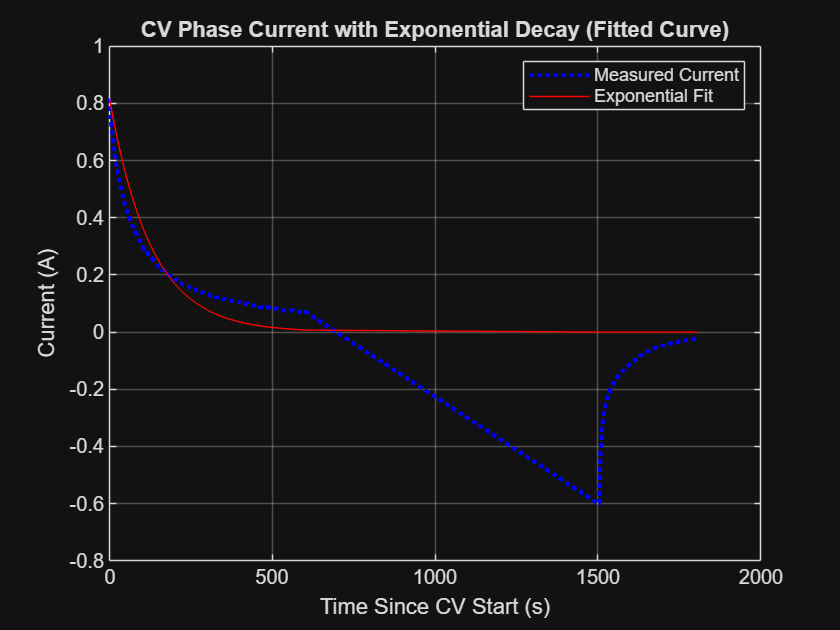


%calculate the fitted current for CC
current_fit_CV = model2(T_CV, time_CV);

% Plot measured data and exponential fit
figure
plot(time_CV, current_CV, 'b', 'LineWidth', 2, 'LineStyle', ':')
hold on
plot(time_CV, current_fit_CV, 'r')
grid on

xlabel('Time Since CV Start (s)')
ylabel('Current (A)')
title('CV Phase Current with Exponential Decay (Fitted Curve)')
legend('Measured Current', 'Exponential Fit', 'Location', 'northeast')


% Display tau
fprintf('CV exponential decay tau = %.2f seconds\n', T_CV)

CV exponential decay tau = 127.32 seconds


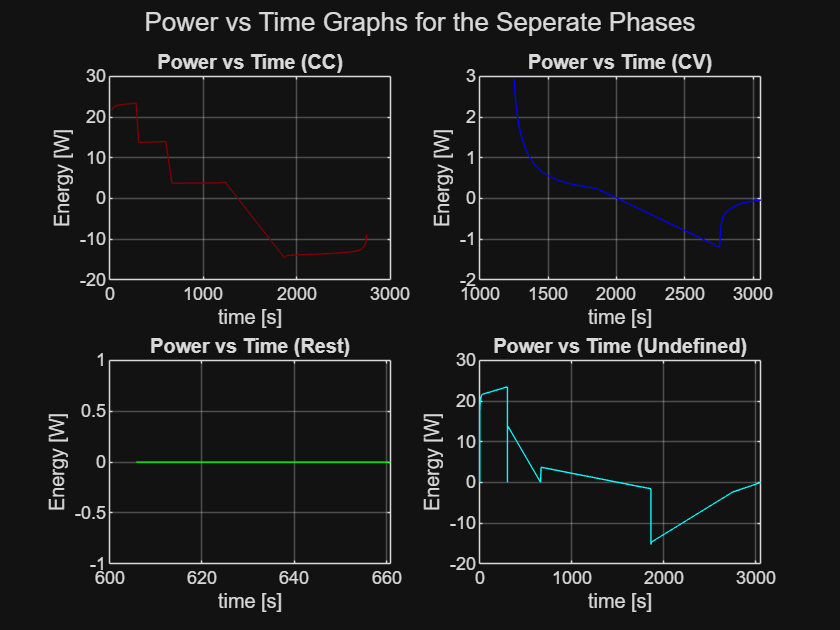


%Step 3
%OPTIONAL: Compare power vs. time during each phase and compute 
% total energy delivered during each phase.

%separating CC and CV (comparing Energy vs time and Power vs time during
%each phase (CC and CV))

%plotting power vs time in each phase
plotPower_phases(time, power, cycle_data.CyclingModes)

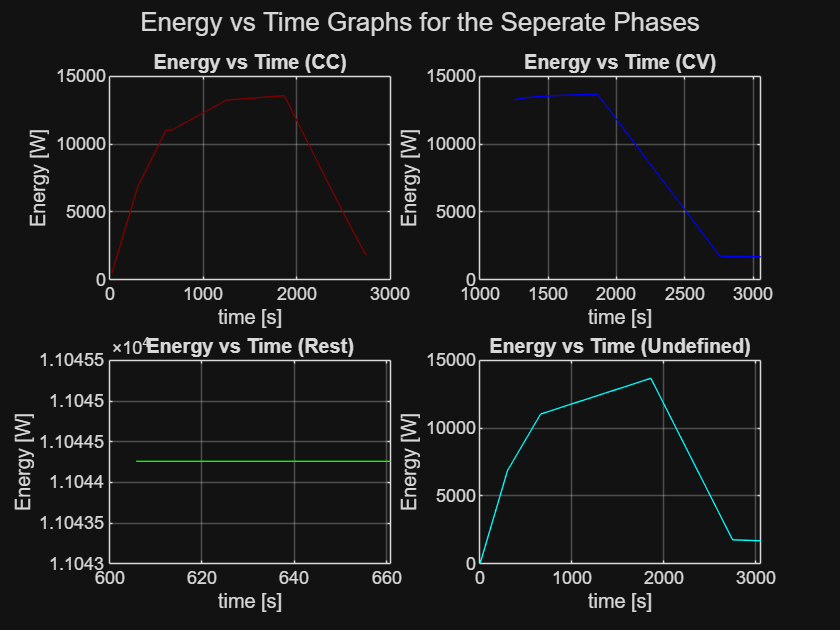

%plotting energy vs time in each phase
plotEnergy_phases(time, energy, cycle_data.CyclingModes)


% OPTIONAL: Identify when most energy is delivered.
%scalar version
energy_CV_tot = trapz(time(CV), power(CV));
energy_CC_tot = trapz(time(CC),power(CC));
energy_Rest_tot = trapz(time(Rest), power(Rest));
energy_Undef_tot = trapz(time(Undefined), power(Undefined));

%displaying the statements
fprintf("Total energy during Constant Voltage (CV) phase: %.4f J", energy_CV_tot)

Total energy during Constant Voltage (CV) phase: -79.7049 J

fprintf("Total energy during Constant Current (CC) phase: %.4f J", energy_CC_tot)

Total energy during Constant Current (CC) phase: -1940.4390 J

fprintf("Total energy during Rest phase: %.4f J", energy_Rest_tot)

Total energy during Rest phase: 0.0000 J

fprintf("Total energy during the Undefined phase: %.4f J", energy_Undef_tot)

Total energy during the Undefined phase: 2564.2266 J


%Identifying when the most energy is delivered (in CC and CV phases)
if abs(energy_CC_tot) > abs(energy_CV_tot)
    fprintf("The most energy is delivered during the constant current (CC) phase (%.2f J)\n", abs(energy_CC_tot))
else
    fprintf("The most energy is delivered during the constant voltage (CV) phase (%.2f J)\n", abs(energy_CV_tot))
end

The most energy is delivered during the constant current (CC) phase (1940.44 J)



% OPTIONAL: Identify when charging is most efficient.

%calculating energy loss as a scalar 
E_loss_CC = trapz(time(CC), Power_loss(CC)); 
E_loss_CV = trapz(time(CV), Power_loss(CV)); 
E_loss_Rest = trapz(time(Rest), Power_loss(Rest)); 
E_loss_Undef = trapz(time(Undefined), Power_loss(Undefined));

%identifying when the charging is the most efficient
e_CC = ((abs(energy_CC_tot) - abs(E_loss_CC))/abs(energy_CC_tot))*100; 
e_CV = ((abs(energy_CV_tot) - abs(E_loss_CV))/abs(energy_CV_tot))*100; 
e_rest = ((abs(energy_Rest_tot) - abs(E_loss_Rest))/abs(energy_Rest_tot))*100; 
e_undef = ((abs(energy_Undef_tot) - abs(E_loss_Undef))/abs(energy_Undef_tot))*100;

%displaying the values 
efficiency_in_phases = table(e_CC, e_CV, e_rest, e_undef, 'VariableNames', ...
    {'CC', 'CV', 'Rest', 'Undefined'});
fprintf("Efficiency Across Phases (%%):")

Efficiency Across Phases (%):

disp(efficiency_in_phases)

     CC        CV      Rest    Undefined
    _____    ______    ____    _________

    63.31    95.649    NaN      82.182  




%determining which is the most efficient phase (CV or CC)

if abs(e_CC) > abs(e_CV)
    fprintf("Constant Current (CC) phase is the most efficient (%.4f%%)\n", abs(e_CC))
else
    fprintf("Constant Voltage (CV) phase is the most efficient (%.4f%%)\n", abs(e_CV))
end

Constant Voltage (CV) phase is the most efficient (95.6487%)


## **Interpretation of Results**

**Summarize your findings by interpreting their physical/engineering meaning (for example, why would engineers want to compute the analytical results in Task 3?):**

**TASK 1:**

- Step 1 (Alex) - The example lithium-ion battery dataset was loaded into MATLAB, and several charging cycles were randomly selected from different points throughout the dataset to observe how the battery's charging behavior changed over its lifetime. Since the dataset contains hundreds of charging cycles, sampling cycles from the beginning, middle, and end provided a representative overview without having to analyze every cycle individually. By comparing the voltage and current curves, it became clear that the battery's charging profile degraded as it aged. The user of the livescript is then prompted to make a cycle number selection after seeing 12 example charging curves interspersed through the dataset. Given the degradation of charging cycles, we recommend Cycle 1 as a selection, but chose to still make the cycle selection option to keep it interactive (this input prompt appears in the Command Window). Cycle 1 is recommended because it had the smoothest voltage and current curves with the fewest discontinuities, making it the best candidate for fitting a simple RC charging model.

- Step 2 (Alex) - The battery data was preprocessed to isolate only the charging portion of Cycle 1 (later changed to apply to any user-selected cycle number). Since the goal was to model the charging profile, removing the discharging portion ensured that the analytical model was fit only to the relevant data. This preprocessing step improves the accuracy of the curve fit and allows the charging behavior to be analyzed without interference from the discharge cycle.

- Step 3 (Alex) - The charging voltage data was fit to a simple RC capacitor charging equation using MATLAB's curve fitting tools. Since the battery's maximum voltage of 3.6 V was already known, the only unknown parameter was the RC time constant, τ. This value represents how quickly the battery approaches its maximum charging voltage. Engineers estimate this parameter because it provides a simple mathematical model of the battery's charging behavior, which can be used to predict charging performance, compare batteries, and develop battery management system (BMS) algorithms.

- Step 4 (Alex) - The measured charging data and fitted RC model were plotted on the same graph to visually compare how well the analytical equation matched the experimental battery data. The fitted curve closely followed the overall charging trend, showing that a first-order RC model provides a reasonable approximation of the battery's charging profile, even though real lithium-ion batteries exhibit more complex electrochemical behavior.

- Step 5 (Alex) - The goodness-of-fit errors, including the sum of squared errors (SSE), root mean squared error (RMSE), and coefficient of determination (R²), were calculated to evaluate how well the RC model matched the measured charging data. These values provide a quantitative measure of the model's accuracy, with lower SSE and RMSE values and an R² value closer to 1 indicating a better fit. Engineers use these errors to determine whether a simplified analytical model is accurate enough for predicting battery behavior, comparing different battery models, and supporting the development of battery management systems.

**TASK 2:**

- Step 1 (Chris) - The Voltage vs Time graph shows how the battery’s terminal voltage increases throughout the charging cycle. The voltage initially has a steep incline (for cycle 1) during the CC phase, then steadily tapers as it reaches the battery’s maximum charging voltage (in the CV phase). Engineers analyze this voltage profile as it provides insight to the battery’s charging patterns as well as the health. The shape of the curve that is created is a basis for several of the analytical calculations prevalent in task 3, such as the rate of voltage charge, and the duration of time required to reach certain percentages of charge. These calculations help engineers improve the efficiency of the battery.

- Step 2 (Chris) - The Current vs. Time graph depicts how the charging current changes throughout the charging process. In cycle 1, the battery’s current remains constant during the CC phase, as to transfer energy into the battery, and once the battery reaches max voltage, it switches to the CV phase until the charging is complete. The analysis of current behavior is important as it determines the amount of heat generated in the battery, which is important information to help engineers improve the efficiency of the battery, minimize the amount of heat loss, and improve the lifespan of the battery.

- Step 3 (Vincenzo) - The power vs time graph displays the rate of energy transfer throughout one of the battery’s charging cycles. Engineers are able to analyze this data in order to identify periods of high energy transfer, any unusual discrepancies or gaps, and evaluate the efficiency of the charging processes. We can also compute the total amount of energy transferred by integrating the area under the curve, which is done during Step 3 of Task 3.

**TASK 3:**

- Step 1 (Vincenzo) - The numerical derivative of voltage with respect to time was calculated in this section, which mainly allows engineers to visually observe the battery’s charging characteristics after graphing the data. Instead of looking at a voltage vs time graph, the rate-of-change data provides much more insight on how rapidly the voltage is changing throughout the entire cycle. The minimum and maximum points help us identify important phases of the charging process and will be useful when trying to improve the overall efficiency of the battery’s charging.

- Step 2 - Determining the time needed to reach 80% and 100% charge essentially tells us how fast the battery can charge to both an acceptable amount, and its maximum capacity. These benchmarks help engineers compare charging methods while also maintaining healthy battery life for long term use. Too slow of a charge is undesirable while too fast of a charge can lead to increased battery decay and internal stress, so charging times are very significant pieces of data to pay close attention to.

- Step 3 - Calculating the total energy delivered to the battery during the charging cycle gives us valuable insight on how much charge is being stored in the battery at any given point. Since this data is taken during the battery’s charging phase, it should be apparent that the total energy (J) is positive. This metric is useful because it allows engineers to evaluate the battery’s performance, estimate costs, and determine how efficiently the battery can hold its charge. Undesirable discharge and current leakage are common problems for batteries, so it’s vital to understand the properties of the battery.

- Step 4 (Chris) - The calculations of resistive energy loss helps estimate how much energy is converted into heat due to the battery’s internal resistance while it is charging. Because the current flows through the battery’s internal resistance, some energy is dissipated instead of stored. This value is important to compute to determine the amount of energy wasted, to optimize charging, increase battery lifespan, and improve the efficiency of the battery. These calculations can also help to reduce the amount of heat generated during charging.

**What are some limitations of your work?**

    Some limitations of the work include experience with MATLAB coding, due to inexperience in current levels of programming leading to primitive coding techniques. Another limitation includes time and responsibilities. Although we were given a specific amount of time to complete our project, other responsibilities outside of this internship, including school, jobs, and extracurriculars, limit the amount of time we are able to dedicate to completing the advanced portions. Lastly, our analysis is only based on the data given to us, for example voltage, current, temperature, internal resistance. Thus, the results may not fully represent the true nature of the battery under different environments.

**What are practical next steps?**

    Practical next steps for this project would be to determine and plot the rate of change of the current/power with respect to time, as that was an analysis required for voltage. This analysis could provide greater insight about how rapidly the charging conditions can change during each phase. Another step could be to determine what factors could have an effect on the internal resistance of the battery, such as temperature, or testing different charging profiles with the use of Simscape battery.

**See File Here:**

[https://docs.google.com/document/d/1_is4KNqUnRwVTSIir-Yf8FZxwg2MMpAIxmkzQo0h1PQ/edit?usp=sharing](https://docs.google.com/document/d/1_is4KNqUnRwVTSIir-Yf8FZxwg2MMpAIxmkzQo0h1PQ/edit?usp=sharing) 